V0 = 0.895;
C1 = 38.72e-12;
Ron = 213;
Fs = 5E6;
VDD = 1.8;
Vth = 0.457;
Fin = 51/512*Fs;
win = Fin * 2 * pi;
timeoffset = 150e-9;
t = linspace(timeoffset,51/Fin + timeoffset,512*16);
Sine = [sin(win.*t); sin(2*win.*t); sin(3*win.*t)];
COS = [-1.*ones(size(t)); cos(win.*t); -1*cos(2*win.*t); cos(3*win.*t)];


## Rebuild VMOS (Vs - Vd)

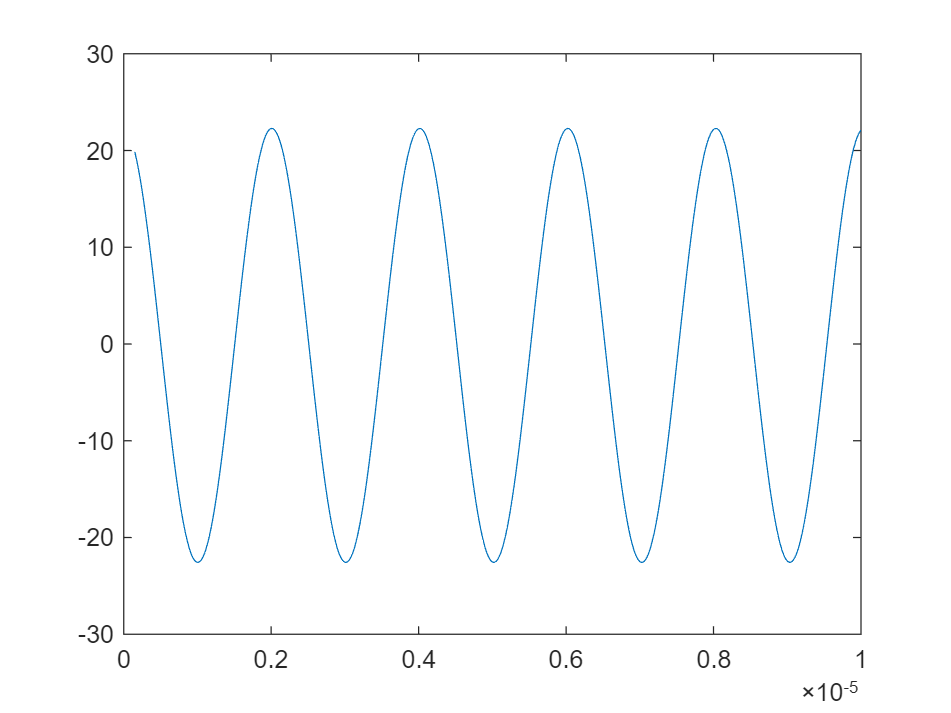

VMOS_db = [-82.66, -32.99, -82.65, -97.14];

VMOS_mag = db2mag(VMOS_db) * COS * 1000;

figure
box on; grid on;
plot(t,VMOS_mag)
xlim([0, 0.1E-4])

max(VMOS_mag)

ans = 22.2796

min(VMOS_mag)

ans = -22.5742

mag2db(abs(max(VMOS_mag) + min(VMOS_mag))/1000/2/2)

ans = -82.6550

## Rebuild Id

Id_db = [-79.29, -154.96, -165.93];
Id_mag = db2mag(Id_db);
Id2Vout_dB = mag2db(Id_mag .* [1/(win*C1), 1/(2*win*C1), 1/(3*win*C1)])

Id2Vout_dB =    -0.9577  -82.6483  -97.1401


从Id  -> Vout是成立的，即：


$$V_{out} (s)= I_{d}(s) \times \frac{1}{SC}$$


## Rebuild Ron

Ron_db = [46.29, 2.66, -11.06];
Ron_mag = db2mag(Ron_db)

Ron_mag =   206.3004    1.3583    0.2799


Ron2Vsd = V0*win*C1 .* [Ron_mag(2)/2, ...
            Ron_mag(1), Ron_mag(2)/2, Ron_mag(3)/2]

Ron2Vsd =     0.0001    0.0224    0.0001    0.0000


mag2db(Ron2Vsd)

ans =   -82.6564  -33.0058  -82.6564  -96.3764
